ts=0.6;
fs=1/ts

fs = 1.6667


N=512;
k=0:N-1;
td=k*ts;
p0=70;
f0=fs/6;%cumpliendo el teorema de nyquist
w=2*pi*f0

w = 1.7453

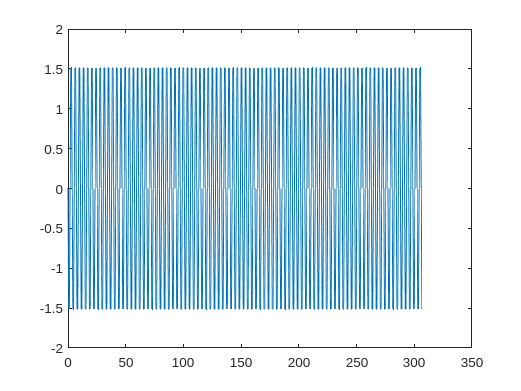

v0=1;
x_n=-(v0*w)*sin(w*td);
plot(td,x_n)

v=[x_n ;zeros(1,N)]';

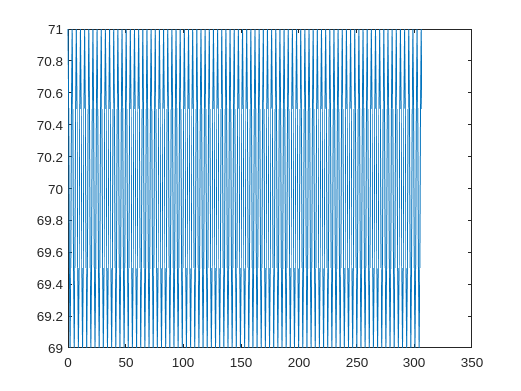

A=v0;
p_n=p0+A*cos(w*td);
figure
plot(td,p_n)

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

a=sqrt(p_n.^2+ (b/2)^2);%lados iguales del triangulo isosceles
h=p_n;
alpha123=asin(h./a);

alpha231=alpha123;
alpha312=pi-2*alpha123;
pn=zeros(4,1);

for i=2:N
    Dalpha123=(alpha123(i)-alpha123(i-1))/ts;
    Dalpha312=(alpha312(i)-alpha312(i-1))/ts;
    Dalpha231=(alpha231(i)-alpha231(i-1))/ts;
    if Dalpha312 ~= 0
        m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231,Dalpha123,Dalpha312);
        m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123,Dalpha312);
        m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123,Dalpha231,m2_12,m2_21);
        M2_123_inv=inv(m2_123);
        pn=m2_123\[sin(alpha123(i))*(rot(alpha312(i)))'*v(i,[1 2])' - sin(alpha231(i))*v(i,[1 2])';sin(alpha231(i))*(rot(alpha231(i)))'*v(i,[1 2])']
    
    end
end

pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

    0.1875
   -0.0722
    0.0759
    0.0480


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.3921
   -0.1460
    0.1546
    0.0958


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

    0.1216
   -0.0468
    0.0492
    0.0311


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.7841
   -0.2919
    0.3092
    0.1916


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

    0.2027
   -0.0781
    0.0820
    0.0519


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.2542
   -0.0947
    0.1002
    0.0621


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

    0.2837
   -0.1093
    0.1149
    0.0726


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-11 *

    0.1568
   -0.0584
    0.0618
    0.0383


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

    0.3648
   -0.1405
    0.1477
    0.0933


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.4237
   -0.1578
    0.1671
    0.1035


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

   -0.7300
    0.2812
   -0.2955
   -0.1868


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.5085
   -0.1893
    0.2005
    0.1242


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-11 *

    0.1703
   -0.0656
    0.0689
    0.0436


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-12 *

    0.5932
   -0.2209
    0.2339
    0.1450


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 	1.0e+-12 *

   -0.5679
    0.2188
   -0.2299
   -0.1453


pn =   286.8813
 -109.5664
  115.3663
   72.5488


pn =   146.6723
  -55.0700
   58.2116
   36.2486


pn = 	1.0e+-11 *

    0.3136
   -0.1168
    0.1237
    0.0766


pn =   299.3973
 -112.4125
  118.8254
   73.9930


pn =   146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.1865
   -0.0718
    0.0755
    0.0477


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

    0.7627
   -0.2840
    0.3007
    0.1864


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.1946
   -0.0750
    0.0788
    0.0498


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

    0.8475
   -0.3155
    0.3342
    0.2071


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.4379
   -0.1687
    0.1773
    0.1120


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.1526
    0.0568
   -0.0602
   -0.0373


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2108
   -0.0812
    0.0853
    0.0539


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.1017
   -0.0379
    0.0401
    0.0248


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

   -0.1625
    0.0626
   -0.0658
   -0.0416


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.3560
   -0.1326
    0.1404
    0.0870


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.2433
    0.0937
   -0.0985
   -0.0623


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.1186
   -0.0442
    0.0468
    0.0290


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.4703
   -0.1812
    0.1904
    0.1203


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.1187
    0.0442
   -0.0468
   -0.0290


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2432
   -0.0937
    0.0985
    0.0622


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.6273
   -0.2336
    0.2473
    0.1533


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

    0.1617
   -0.0623
    0.0655
    0.0414


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.3899
   -0.1452
    0.1537
    0.0953


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2594
   -0.0999
    0.1050
    0.0664


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.1525
   -0.0568
    0.0601
    0.0373


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.5027
   -0.1937
    0.2035
    0.1286


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4069
   -0.1515
    0.1604
    0.0994


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.1947
    0.0750
   -0.0788
   -0.0498


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.1695
   -0.0631
    0.0668
    0.0414


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.5189
   -0.1999
    0.2101
    0.1328


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.9155
   -0.3409
    0.3610
    0.2237


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2919
   -0.1124
    0.1182
    0.0747


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.3053
    0.1137
   -0.1204
   -0.0746


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

    0.6481
   -0.2497
    0.2624
    0.1658


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4408
   -0.1641
    0.1738
    0.1077


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.7784
   -0.2999
    0.3151
    0.1992


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.2034
   -0.0757
    0.0802
    0.0497


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.3893
    0.1500
   -0.1576
   -0.0996


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

   -0.3398
    0.1265
   -0.1340
   -0.0830


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.3243
   -0.1249
    0.1313
    0.0830


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.7120
   -0.2651
    0.2808
    0.1740


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1038
   -0.0400
    0.0420
    0.0266


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.5087
    0.1894
   -0.2006
   -0.1243


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.1298
    0.0500
   -0.0526
   -0.0332


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.2373
   -0.0883
    0.0936
    0.0580


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.5838
   -0.2249
    0.2363
    0.1494


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.9833
   -0.3661
    0.3877
    0.2403


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.3567
   -0.1374
    0.1444
    0.0913


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.2375
    0.0884
   -0.0936
   -0.0580


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.1297
   -0.0500
    0.0525
    0.0332


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.5086
   -0.1893
    0.2005
    0.1243


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.8433
   -0.3249
    0.3414
    0.2157


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1255
   -0.0467
    0.0495
    0.0307


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.6162
   -0.2374
    0.2495
    0.1577


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

    0.3381
   -0.1259
    0.1333
    0.0826


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.3891
   -0.1499
    0.1575
    0.0996


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.7798
   -0.2903
    0.3075
    0.1906


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1103
   -0.0425
    0.0446
    0.0282


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.5425
   -0.2020
    0.2139
    0.1326


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

   -0.6497
    0.2503
   -0.2630
   -0.1662


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.3051
   -0.1136
    0.1203
    0.0745


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.2920
    0.1125
   -0.1182
   -0.0747


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1051
   -0.0391
    0.0414
    0.0257


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.4216
   -0.1624
    0.1707
    0.1079


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.8137
   -0.3030
    0.3209
    0.1988


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.1945
   -0.0749
    0.0787
    0.0498


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.4070
    0.1515
   -0.1605
   -0.0995


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.9081
   -0.3498
    0.3676
    0.2323


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.3390
   -0.1262
    0.1337
    0.0828


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1622
   -0.0625
    0.0657
    0.0415


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1085
   -0.0404
    0.0428
    0.0265


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.4867
    0.1875
   -0.1970
   -0.1245


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1831
   -0.0682
    0.0722
    0.0447


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2269
   -0.0874
    0.0919
    0.0581


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.6103
   -0.2272
    0.2406
    0.1491


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.9405
   -0.3623
    0.3807
    0.2406


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.6105
    0.2273
   -0.2407
   -0.1492


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1654
   -0.0637
    0.0670
    0.0423


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.1355
   -0.0505
    0.0534
    0.0331


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.4864
   -0.1874
    0.1969
    0.1245


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.8815
   -0.3282
    0.3476
    0.2154


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.6813
    0.2625
   -0.2758
   -0.1743


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1628
   -0.0606
    0.0642
    0.0398


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

    0.3230
   -0.1244
    0.1308
    0.0826


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4068
   -0.1515
    0.1604
    0.0994


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.7459
   -0.2874
    0.3020
    0.1908


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.8140
    0.3031
   -0.3210
   -0.1989


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1460
   -0.0562
    0.0591
    0.0373


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

   -0.6797
    0.2531
   -0.2680
   -0.1661


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.2173
   -0.0837
    0.0880
    0.0556


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.6781
   -0.2525
    0.2674
    0.1657


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.8759
    0.3374
   -0.3546
   -0.2241


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1424
   -0.0530
    0.0562
    0.0348


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.1623
    0.0625
   -0.0657
   -0.0415


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.2170
   -0.0808
    0.0856
    0.0530


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.5513
   -0.2124
    0.2232
    0.1410


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

   -0.1017
    0.0379
   -0.0401
   -0.0249


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1265
   -0.0487
    0.0512
    0.0324


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.2714
    0.1011
   -0.1070
   -0.0663


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1978
   -0.0762
    0.0801
    0.0506


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4746
   -0.1767
    0.1871
    0.1160


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.8108
   -0.3123
    0.3282
    0.2074


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1221
   -0.0454
    0.0481
    0.0298


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.3570
    0.1375
   -0.1445
   -0.0913


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1967
   -0.0732
    0.0775
    0.0481


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.3566
   -0.1374
    0.1444
    0.0912


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.7459
   -0.2777
    0.2941
    0.1823


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1070
   -0.0412
    0.0433
    0.0274


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.4749
    0.1768
   -0.1873
   -0.1160


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1784
   -0.0687
    0.0722
    0.0456


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.2711
   -0.1009
    0.1069
    0.0662


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.6161
   -0.2374
    0.2494
    0.1576


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1017
   -0.0379
    0.0401
    0.0249


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.5516
    0.2125
   -0.2233
   -0.1411


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1763
   -0.0656
    0.0695
    0.0431


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.1620
   -0.0624
    0.0656
    0.0414


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.2509
   -0.0934
    0.0989
    0.0613


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.8756
   -0.3373
    0.3545
    0.2240


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1288
   -0.0480
    0.0508
    0.0315


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1589
   -0.0612
    0.0643
    0.0407


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-12 *

    0.6763
   -0.2518
    0.2667
    0.1652


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.2303
   -0.0887
    0.0932
    0.0589


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.8136
   -0.3029
    0.3208
    0.1988


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1135
   -0.0437
    0.0460
    0.0290


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1560
   -0.0581
    0.0615
    0.0381


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

   -0.3263
    0.1257
   -0.1321
   -0.0835


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.2306
   -0.0858
    0.0909
    0.0563


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.6810
   -0.2623
    0.2757
    0.1742


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1085
   -0.0404
    0.0428
    0.0265


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1395
   -0.0537
    0.0565
    0.0357


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.1359
    0.0506
   -0.0536
   -0.0332


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.2108
   -0.0812
    0.0853
    0.0539


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.6102
   -0.2272
    0.2406
    0.1491


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.9405
   -0.3623
    0.3807
    0.2406


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.6106
    0.2273
   -0.2408
   -0.1492


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1654
   -0.0637
    0.0670
    0.0423


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.2102
   -0.0783
    0.0829
    0.0514


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.4863
   -0.1874
    0.1969
    0.1244


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.8814
   -0.3282
    0.3476
    0.2154


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.6814
    0.2625
   -0.2758
   -0.1743


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1627
   -0.0606
    0.0642
    0.0398


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1914
   -0.0737
    0.0775
    0.0490


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4067
   -0.1514
    0.1604
    0.0994


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.7458
   -0.2873
    0.3019
    0.1908


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

   -0.8141
    0.3031
   -0.3210
   -0.1989


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1459
   -0.0562
    0.0591
    0.0373


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.1899
   -0.0707
    0.0749
    0.0464


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

    0.2917
   -0.1124
    0.1181
    0.0746


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.6780
   -0.2524
    0.2673
    0.1657


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-11 *

   -0.8760
    0.3375
   -0.3546
   -0.2241


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.3391
   -0.1262
    0.1337
    0.0829


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.1719
   -0.0662
    0.0696
    0.0440


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.2170
   -0.0808
    0.0856
    0.0530


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

   -0.1330
    0.0512
   -0.0538
   -0.0340


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

   -0.1018
    0.0379
   -0.0401
   -0.0249


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-10 *

    0.3146
   -0.1212
    0.1274
    0.0805


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-10 *

    0.3662
   -0.1363
    0.1444
    0.0895


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930


pn = 4×1
  146.4195
  -55.9209
   58.8810
   37.0277


pn = 4×1
	1.0e+-12 *

    0.9707
   -0.3740
    0.3930
    0.2484


pn = 4×1
  286.8813
 -109.5664
  115.3663
   72.5488


pn = 4×1
  146.6723
  -55.0700
   58.2116
   36.2486


pn = 4×1
	1.0e+-11 *

    0.4745
   -0.1767
    0.1871
    0.1159


pn = 4×1
  299.3973
 -112.4125
  118.8254
   73.9930
